## ii)

I=double(imread('cameraman.pgm'))/255;
I_t=imrotate(I,45);
imwrite(I,'I.pgm');
imwrite(I_t,'I_t.pgm');
system('siftDemoV4\siftWin32 <I.pgm>I.key');

Finding keypoints... 
336 keypoints found. 


system('siftDemoV4\siftWin32 <I_t.pgm>I_t.key');

Finding keypoints... 
404 keypoints found. 


[xyso,F]=create_feature_matrices('I.key');
[xyso_t,F_t]=create_feature_matrices('I_t.key');
D=pairwise_distance(F,F_t);
P=paired_keypoints(D,0.6);
t=estimate_affine_transformation(P,xyso,xyso_t);

disp('Vector t: ')

Vector t: 


disp(t)

    0.6977
   -0.7322
    0.7005
    0.6887
  186.6140
    4.7505




T=[t(1),t(2),t(5);t(3),t(4),t(6);0,0,1];

disp('Matrix T: ')

Matrix T: 


disp(T)

    0.6977   -0.7322  186.6140
    0.7005    0.6887    4.7505
         0         0    1.0000



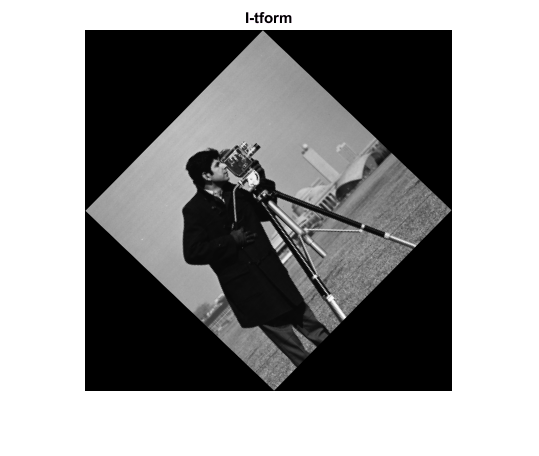


tform=invert(affine2d(T'));
I_tform=imwarp(I,tform);

figure, imshow(I_tform),title('I-tform')

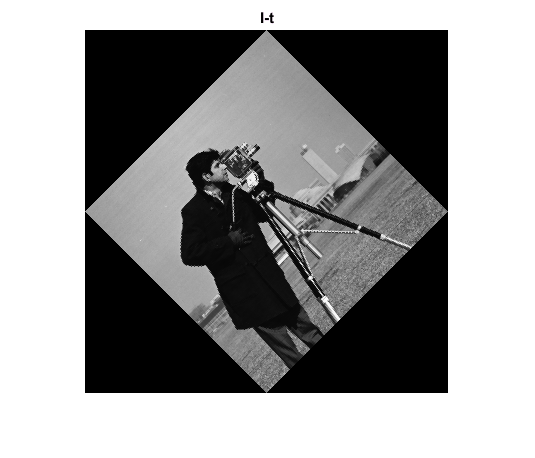

figure, imshow(I_t),title('I-t')

As it can be seen in the figures, I_t and I_tform are quite similar The general form of I_t and I_tform are similar. However, I_tform appears to have smoother edges. The other difference is the image sizes. I_t is 363x363 and I_tform is 361x367.

## iii)

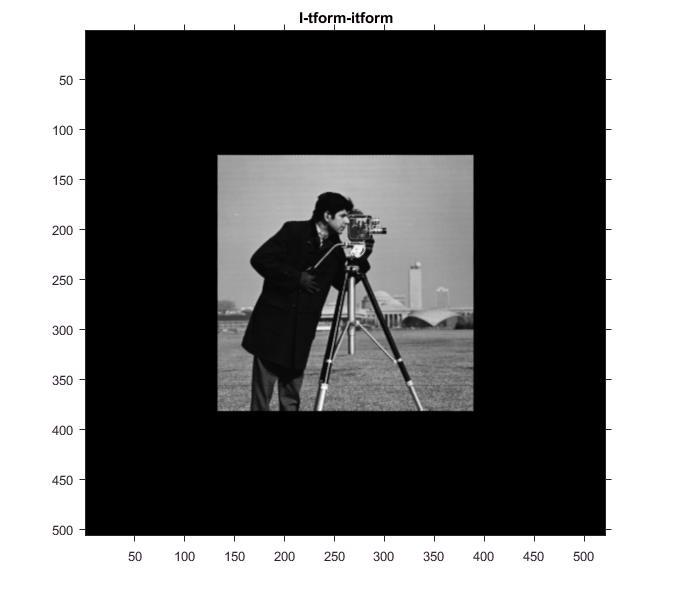

itform=invert(tform);
I_tform_itform=imwarp(I_tform,itform);
figure, imshow(I_tform_itform), title('I-tform-itform')
axis on

I_tform_itform has a bigger size (506x521) than I (256x256). However, the inner 256x256 block of I_tform_itform looks like I. By visual inspection, It seems I_tform_itform is slightly smoother than I. it was expected because here only a transform and inverse transform is applied on the image.

## iv)

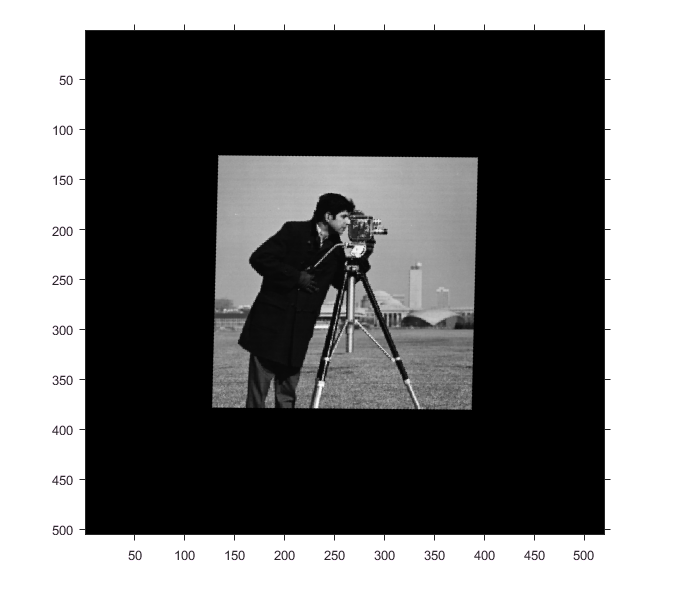

I_t_itform=imwarp(I_t,itform);
figure, imshow(I_t_itform)
axis on

Again the inner part of I_t_itform looks like I. However there are more  visible differences this time. Although they seem to be less different in terms of smoothness of edges, I_t_itform seem to be skewed or it is as if  two shear transforms in both directions with a small factor have been applied to I to result I_t_itform or vice versa .

## v)

I=double(imread('cameraman.pgm'))/255;
I_t=imrotate(I,45);

imwrite(I,'I.pgm');
imwrite(I_t,'I_t.pgm');
system('siftDemoV4\siftWin32 <I.pgm>I.key');

Finding keypoints... 
336 keypoints found. 


system('siftDemoV4\siftWin32 <I_t.pgm>I_t.key');

Finding keypoints... 
404 keypoints found. 


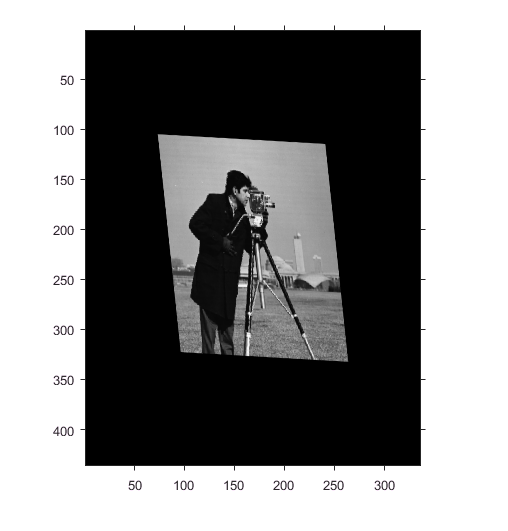

[xyso,F]=create_feature_matrices('I.key');
[xyso_t,F_t]=create_feature_matrices('I_t.key');
D=pairwise_distance(F,F_t);
P=paired_keypoints(D,1.00);
t=estimate_affine_transformation(P,xyso,xyso_t);
T=[t(1),t(2),t(5);t(3),t(4),t(6);0,0,1];
tform=invert(affine2d(T'));
itform=invert(tform);
I_t_itform=imwarp(I_t,itform);
figure, imshow(I_t_itform)
axis on

Again, the inner part of I_t_itform (which is smaller than I) loods like I and there seems to be a little edge smoothness difference between I_t_itform and I. another similarity vith last part is that both have the same kind of difference with I which is a shear (skewness) effect in both direction. Difference with the last part is that the shear (skewness) effect is much more visible in this case (both value and sign of shear factors are different) which makes sense, as many more outlier key-point  matches were used to calculate transform object.

## Confidence (number 0 to 100% about your confidence in your performance on this project and optional statement about areas where you are particularly confidence or not):

## 100%

## Difficulty (number 0 to 100%):

## 70%

## Time Spent (hours):

## About 12 hours